# Transient from IIR Filters

Instructions are in the task pane to the left. Complete and submit each task one at a time.

This code creates a watermarked signal. For more information, see the *Generating Signals and Common Signal Operations* module.

[flute,fs] = audioread("./data/NoisyFlute.wav");
flute = flute(1:3*fs);
t = ((0:numel(flute)-1)/fs)';
yin = chirp(t,2200,t(end),2500);
marked = flute + yin*0.0005;

This code creates the IIR filter from ealier in this module.

designedIIR = designfilt("bandpassiir", ...
    "StopbandFrequency1",2100,"PassbandFrequency1",2200, ...
    "PassbandFrequency2",2500,"StopbandFrequency2",2600, ...
    "StopbandAttenuation1",60,"PassbandRipple",1, ...
    "StopbandAttenuation2",60,"SampleRate",fs, ...
    "DesignMethod","cheby1")

designedIIR =  digitalFilter with properties:

            Coefficients: [8×6 double]

   Specifications:
       FrequencyResponse: 'bandpass'
         ImpulseResponse: 'iir'
              SampleRate: 16000
          PassbandRipple: 1
      StopbandFrequency1: 2100
      PassbandFrequency1: 2200
      PassbandFrequency2: 2500
      StopbandFrequency2: 2600
    StopbandAttenuation1: 60
    StopbandAttenuation2: 60
            DesignMethod: 'cheby1'

 Use fvtool to visualize filter
 Use designfilt to edit filter
 Use filter to filter data


yiir = filter(designedIIR,marked);

## Task 1

To estimate the size of the filter transient, you can use the impulse response.

`[``h``,``t``]` `=` `impz``(``df``,``n``,``fs``)`

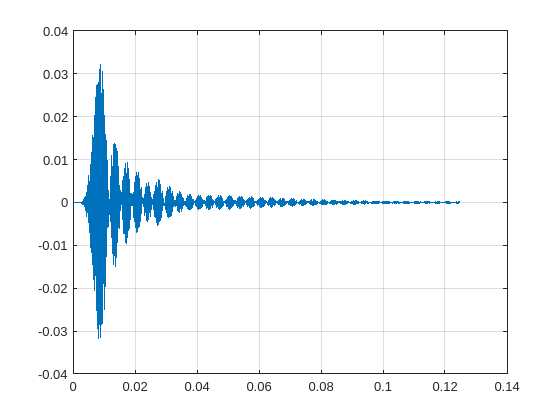

[hi,ti] = impz(designedIIR,2000,fs);
plot(ti,hi)
grid on

## Task 2

The impulse response doesn't reach 0, but it gets very small around 0.05 seconds. Because the transient never gets to 0, you can't truncate the signal to remove it entirely.

Can you see the effects of the transient in the time-domain plot?

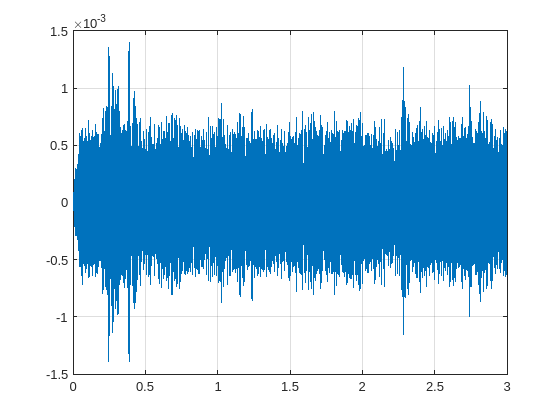

plot(t,yiir)
grid on